# Safe and Scalable Urban Air Mobility Trajectory Planner

This example shows how the proposed multi-agent trajectory planner enables unmanned aerial vehicles (UAVs) to navigate to the assigned destinations while avoiding collision with other agents in the environment. The example is structured in two main sections, demonstrating the two main modules of the proposed framework. Therefore, by the end of this example, you will understand how each module works. 

But first, let's clear the workspace and add all directories to the path.

clear; close all; clc;
addContainingDirAndSubDir;

## Introduction

Urban Air Mobility (UAM) is a novel concept in which partially or fully autonomous air vehicles transport passengers and cargo in dense urban environments. UAM operation is a multi-agent safety-critical application, where safety and scalability are the primary design considerations. Therefore, a UAM trajectory planning framework needs to generate trajectories efficiently while guaranteeing that the generated trajectories satisfy the system’s safety requirements.

The implemented trajectory planner is equipped with two main modules: **Reachability Analysis** and **Markov Decision Process (MDP) based decision-making framework**. In this example, we first go through the reachability analysis module and see how a reachable set can be generated for a given dynamical system. Next, we will see how the implemented reachability analysis module can be integrated with the MDP framework to enable the agents safely navigate to their destination.

### Reachability Analysis

A reachable set of a dynamical system is a set that contains all the possible future states of the system. In this implementation, a data-driven reachability analysis tool known as DryVR has been used to generate the reachable sets of aircraft. DryVR uses the concept of discrepancy function to formulate the reachability analysis problem. A detailed explanation of the tool can be found in [1]. However, the general steps followed to implement the reachability analysis module are:

-  Generate a set of trajectories from the current state of the aircraft.

-   Compute the pairwise maximum distances (Chebyshev distance) between trajectories.

-   Compute the sensitivity parameters using the pairwise maximum distances.

-   Compute the discrepancy parameters. 

-   Define the reachable set using the computed discrepancy parameters.

Now, let's see how the above algorithm is implemented. All the functionalities are implemented inside a classs named "***reachabilityAnalysis."***   

In addition to a simplified kinematic model of fixed-wing aircraft, which is used in this project, we have provided a plug-and-play functionality for the class to take MATLAB's inbuilt UAV dynamic models(both fixed-wing and multi-rotor UAVs) as input.    

%Pick the aircraft type from here 
aircraftType = struct( 'simplified', {'simplified'}, 'fixedwing', {'fixedwing'}, 'multirotor',{'multirotor'});

model = reachabilityAnalysis([100,100,100]); % [x, y, z] position of the vehicle 
tic
Traces = GenerateTraces(model, aircraftType.simplified);
initialRadii = computeInitialRadii(model,Traces);
discrepancyParameters = computeDiscrepancyParameters(model, Traces, initialRadii);
reachTube = getReachtube(model, Traces, initialRadii, discrepancyParameters);
disp('The time taken by the algorithm to comupte the reachable set is '+string(toc)+ 'seconds')

The time taken by the algorithm to comupte the reachable set is 0.21933seconds


save('reachSet')

Now, let's plot the computed reachable set and see what they look like. 

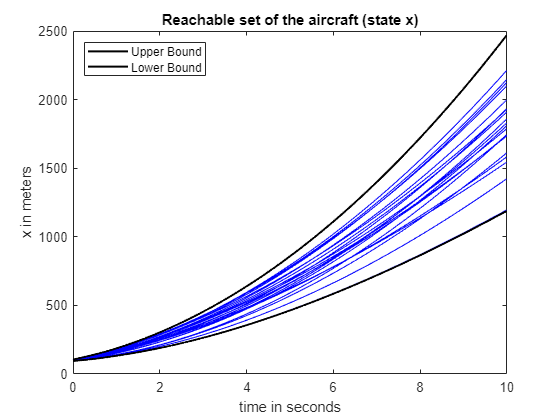

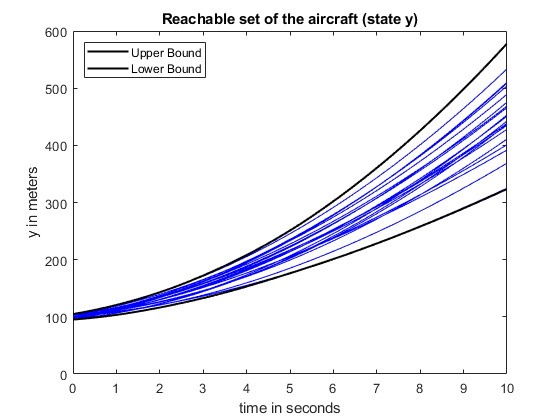

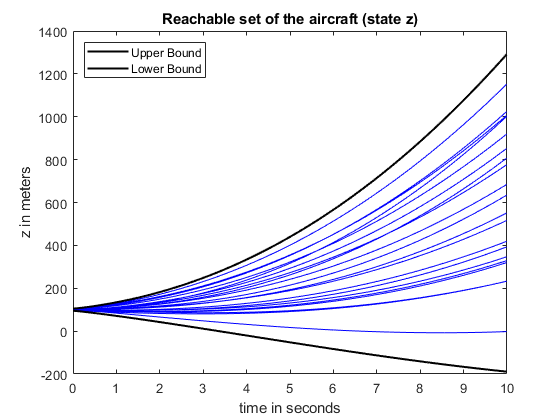

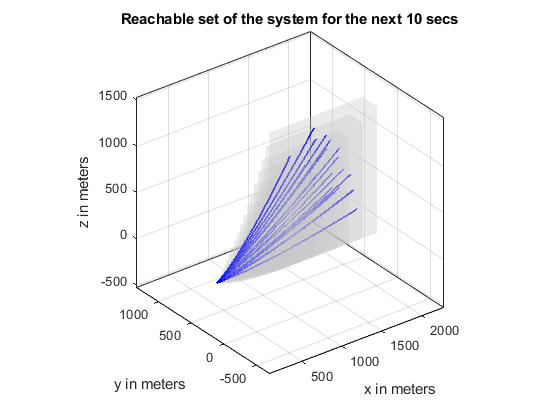

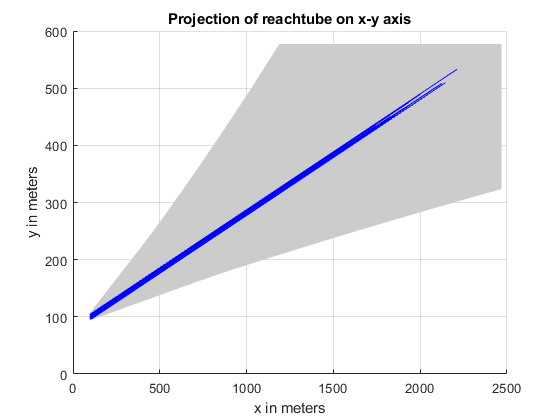

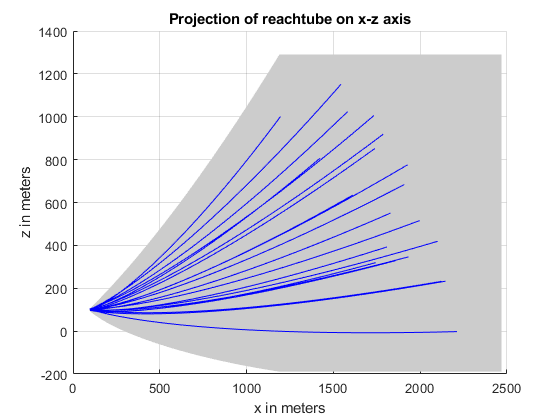

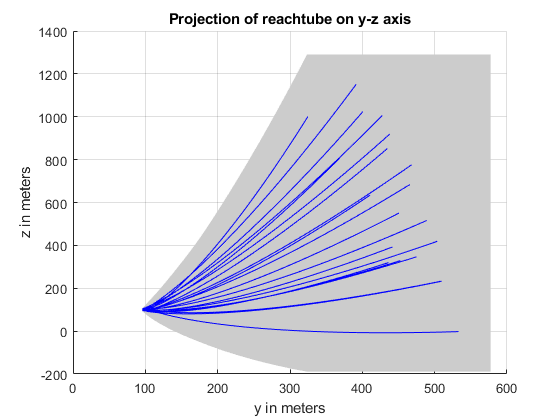

visualizeReachset

Now, we have seen how a reachable set of an aircraft is overapproximated from simulation traces; let's proceed to how the entire trajectory planning framework operates. We start by creating a UAM scenario where the vehicles are supposed to operate in.

### Create Urban Air Mobility Scenario

In this example, we use a simple case where three agents will be assigned to navigate to a goal position. The initial positions of these agents will be generated randomly. In addition, the current implementation allows the user to create a circular scenario where the number of aircraft should be even. Moreover, one can utilize MATLAB's UAV Toolbox's scenario designer feature with a little extra effort.

clear; close all; clc;
parameters;
teamActions = buildActions;
teamLimits = buildLimits;
scenarioSelector = struct('circle','circle', 'random','random');
totalAgents = 3;
droneList = cell(1,totalAgents);
initialStates = scenarioGenerator(totalAgents, scenarioSelector.random);
goals = [10000, 16000, 700];

 Next, let's create three aircraft objects by instantiating the ownship class for each aircraft in the environment. 

for i = 1: totalAgents
    aircraftID = i;
    aircraftTeam = 1;    
    goal = goals;
    baseLatitude = 10;
    baseAltitude = 10;
    droneInitialStates = initialStates(i,:);
    drone = Ownship(aircraftID, aircraftTeam, baseLatitude, baseAltitude, goal);
    drone = updateAircraftStates(drone,  droneInitialStates);
    droneList{i} =  drone;
end

### Simulate Scenario 

Now that everything is set up, we can run the execution. The following block diagram explains a single decision-making step for a single aircraft. 

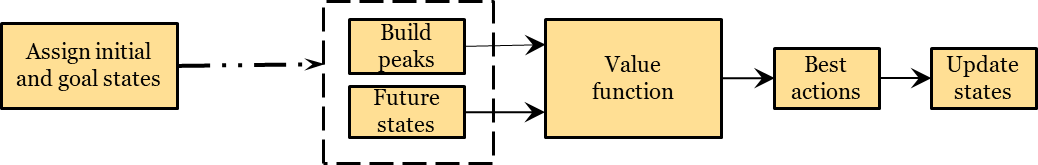

The aircraft first simulates its possible future states using the control inputs from the action space. Then, it identifies the positive and negative reward sources (destination and reachable set of intruders, respectively) and renders the reward magnitude for states that intersect with those reward sources. Next, it computes the value for each future state based on the value function and finally picks a future state with a maximum total value.    

The following block runs the scenario and visualize the execition.  

totalNMACs = 0;
numLeft = size(droneList,2);
stepTimer = [];
while numLeft > 0
    tic
    for k = 1:numel(droneList)
        % The following is the entire operation for aircraft k at step j
        ownship = droneList{k};

        %check if the aircraft is still in the game
        if ownship.dead
            continue
        end

        %build both positive and negative reward sources
        [positivePeaks, negativePeaks] = buildPeaks(ownship, droneList);

        %Forward project all the posible states of the aircraft for the next 10 secs
        [futureStates, oneStepStates, futureActions] = neighboringStates(ownship, teamActions, teamLimits);

        % compute the value for each future state
        totalValues = valueFunction(ownship, futureStates, positivePeaks, negativePeaks);
        
        %select the optimal action
        ownship = selectBestAction(ownship, totalValues, futureActions, futureStates, oneStepStates);

        % update the aircraft state based the selected action
        ownship = updateAircraftStates(ownship,  ownship.nextStates);

        % check if the ownship makes it to goal
        if norm(ownship.currentStates(1:3) - ownship.goal) < 30
            ownship.dead = true;
            disp('ownship ' + string(ownship.aircraftID) + ' made it to goal, removed') 
            numLeft = numLeft -1;
        end

        droneList{k} = ownship;

    end

    % monitor the status of the game
    [terminal, NMACs, droneList] = terminalDetection(droneList);
    totalNMACs = totalNMACs + NMACs;
    stepTimer = [stepTimer,toc];

    if terminal==true
        return
    end
end

ownship 1 made it to goal, removed
ownship 2 made it to goal, removed
ownship 3 made it to goal, removed


save('UAMgame')

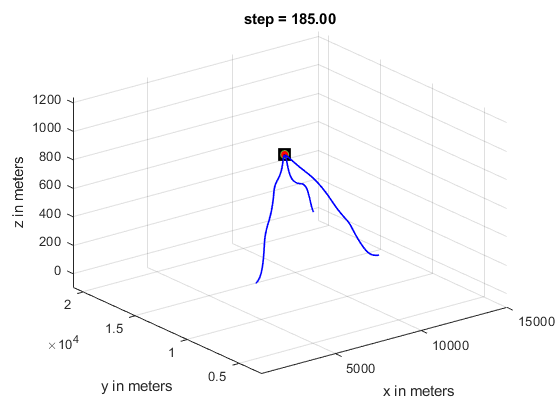

visualizeUAMgame

 **References**

[1] Fan, Chuchu, et al. "Dryvr: data-driven verification and compositional reasoning for automotive systems." *International Conference on Computer Aided Verification*. Springer, Cham, 2017.